# Eksamensæt

**M3NUM1 Anvendte Numeriske Metoder -- 16-01-2023**

**Mathias Bruun Houmøller -- 202006837 -- Au666097**

## Opgave 1

clear
format short %formater resultater til 4 decimaler

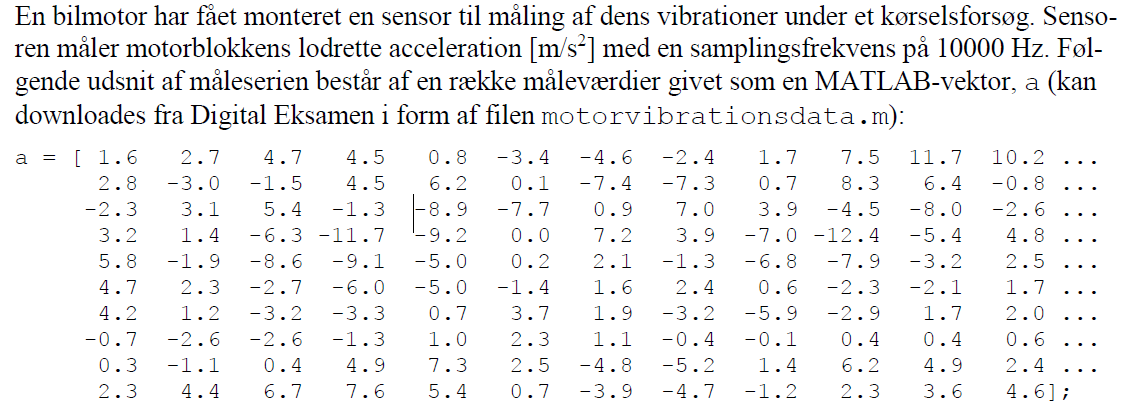

### (1a)

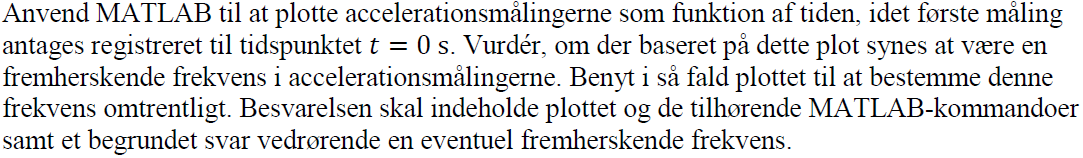

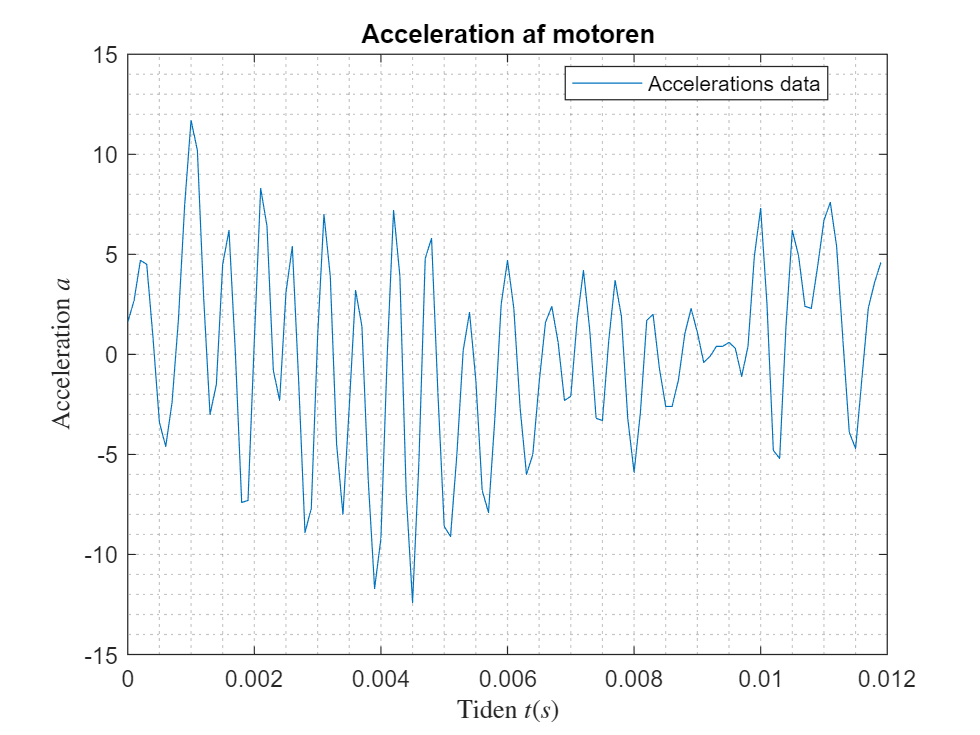

motorvibrationsdata;
dt = 1e-4; % Samplingsinterval (s)
t = 0: dt :(length(a)-1)*dt; %der laves data for tiden
% her trækkes fra og divideres for at få den rigtige dimention.

plot(t,a, 'DisplayName', 'Accelerations data') %data plottes

% formalier
legend('location', 'best')
title('Acceleration af motoren')
xlabel('Tiden $t(s)$', 'interpreter', 'latex')
ylabel('Acceleration $a$', 'interpreter', 'latex')
grid('minor')

Der tælles 20 toppe fra 0 til 0,012 sekunder dermed får vi $f = \frac{20}{0,012} = 1666,7\ Hz$

format long
20/0.012

ans =      1.666666666666667e+03


### (1b)

Bestem den dominerende frekvens i serien af accelerationsmålinger ud fra tidsseriens powerspek-trum. Anfør i besvarelsen den dominerende frekvens samt de MATLAB-kommandoer og –resulta-ter, der har dannet grundlag for bestemmelsen af denne frekvens.

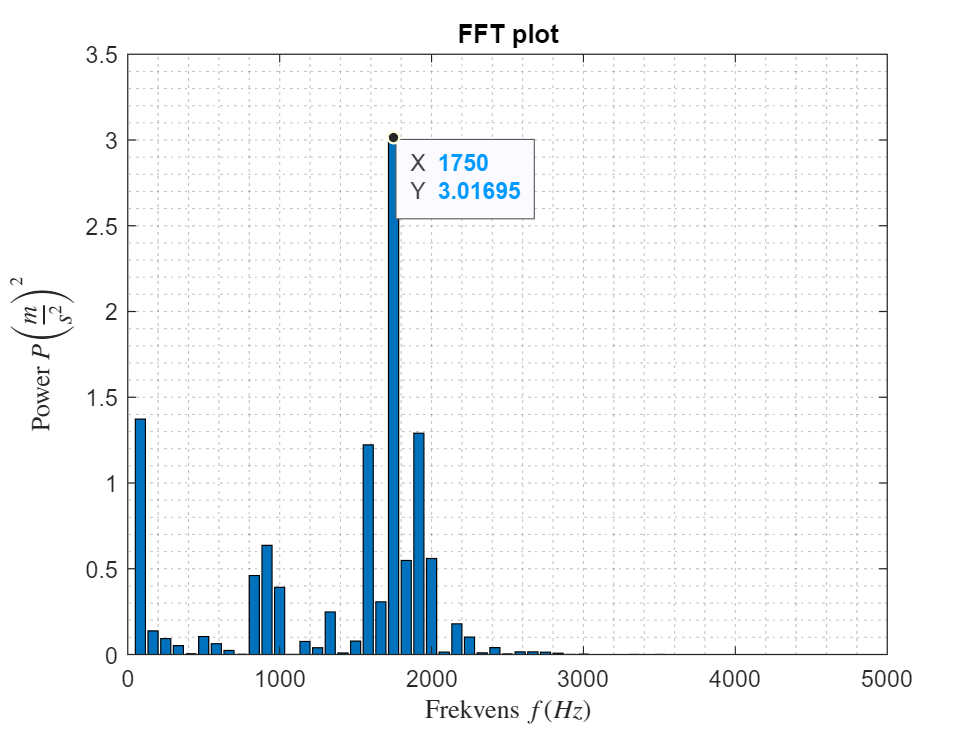

n = length(a);              % Antal samplinger % her vælges alt data som sample
T = n*dt;                   % Signallængde (s) % Tiden det tager at køre smplet igennem
A = fft(a)/n;               % FFT af a (mm)
fs = 1/dt;                  % Samplingsfrekvens (Hz) %Frekvensen hvormed der tages sampels
fmax = fs/2;                % Maks frekvens (Hz)
df = 1/T;                   % Frekvensstep (Hz)
f = (0:n-1)*df;             % Frekvensvektor (Hz) % alle frekvensskridt der gennemgåes
P = real(A).^2 + imag(A).^2;% Powervektor (mm^2) % Her lægges real delen og imaginær delens sammen og forstærkes så de kun er positive
bar(f,P);                   % Plot af powerspektrum %plottes som barplot for bedre overskuelighed
xlim([0 fmax]);             % Afgræns frekvensakse % så der kun ses på et område der ikke gentager en frekvens

% Formalier
title('FFT plot')
xlabel('Frekvens $f(Hz)$', 'interpreter', 'latex')
ylabel('Power $P \left( \frac{m}{s^2} \right)^2 $', 'interpreter', 'latex')
grid('minor')

ax = gca;
chart = ax.Children(1);
datatip(chart,1750,3.017);

result = find(P==max(P)) % vi finder postionen i power vektoren hvor den største frekvens viser sig

result =     22   100


% Her vælges første tal da andet tal blot af en gentagelse af frekvensen
% Vi kan nu finde frekvensen for det stærkeste signam
f_strong = f(22)

f_strong =         1750


**Den dominerende frekvens findes nu til **$1750Hz$**.**

### (1c)

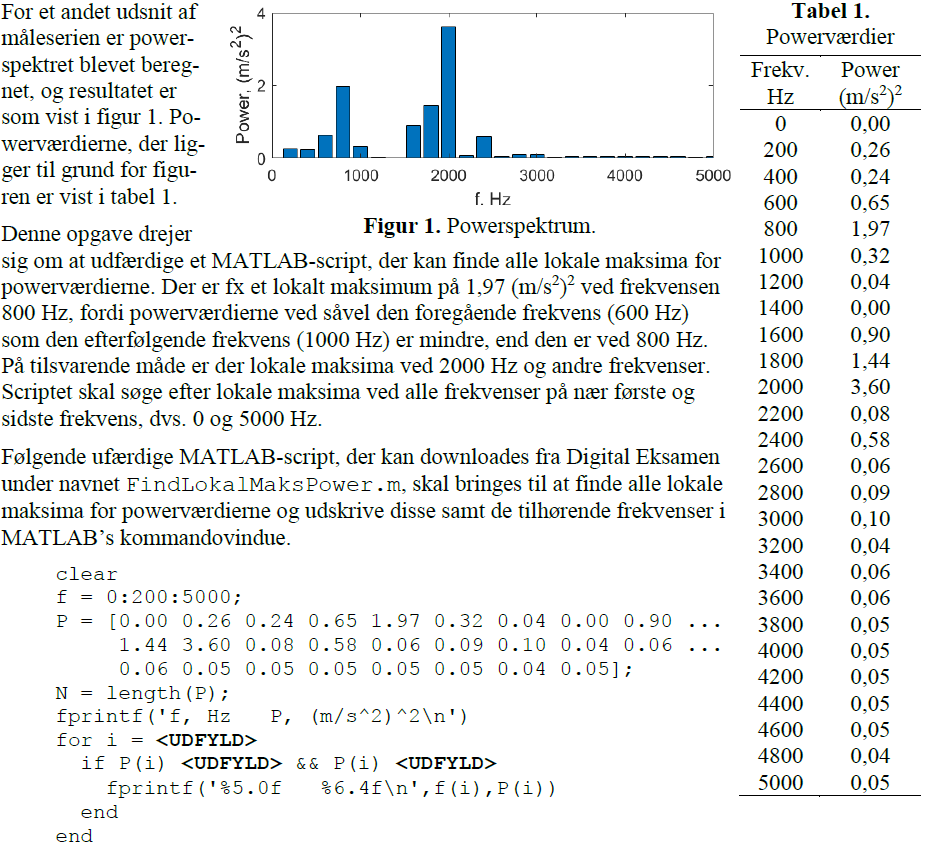

clear
f = 0:200:5000;
P = [0.00 0.26 0.24 0.65 1.97 0.32 0.04 0.00 0.90 ...
    1.44 3.60 0.08 0.58 0.06 0.09 0.10 0.04 0.06 ...
    0.06 0.05 0.05 0.05 0.05 0.05 0.04 0.05];
N = length(P);
fprintf('f, Hz P, (m/s^2)^2\n')

f, Hz P, (m/s^2)^2


for i = 2:N-1
    if P(i) > P(i-1) && P(i) > P(i+1)
        fprintf('%5.0f %6.4f\n',f(i),P(i))
    end
end

  200 0.2600
  800 1.9700
 2000 3.6000
 2400 0.5800
 3000 0.1000


Således findes 5 lokale maximaer og deres styrke, det ses at ved 3000 Hz er den ret lille.

## Opgave 2

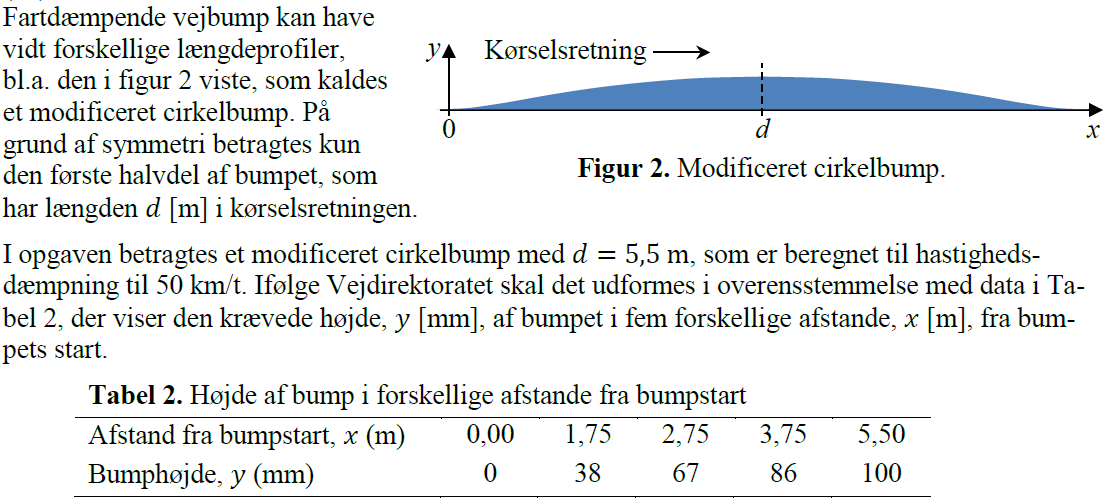

clear
x = [0.00 1.75 2.75 3.75 5.50];
y = [0 38 67 86 100];

### (2a)

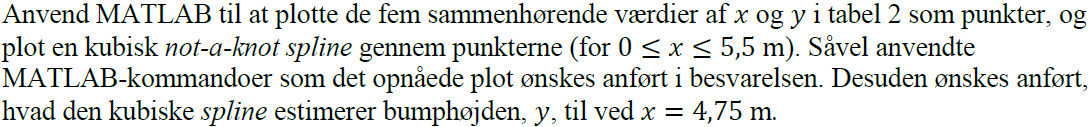

% %der plottes
xx = linspace(x(1), x(end));
yy_spline = spline(x, y, xx);
x_test = 4.75;
yy_spline_test = spline(x, y, x_test)

yy_spline_test = 95.9710

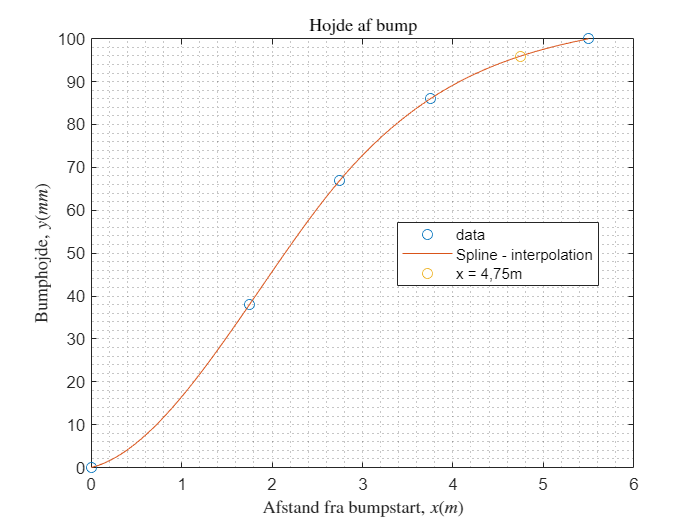

plot(x,y, 'o', 'DisplayName', 'data') %data plottes
hold on
plot(xx, yy_spline, 'DisplayName', 'Spline - interpolation') %data plottes
plot(x_test,yy_spline_test, 'o', 'DisplayName', 'x = 4,75m') %data plottes

% formalier
legend('location', 'best')
title('Hojde af bump', 'interpreter', 'latex')
xlabel('Afstand fra bumpstart, $x(m)$', 'interpreter', 'latex')
ylabel('Bumphojde, $y(mm)$', 'interpreter', 'latex')
grid('minor')
hold off

**Højden vil således være 96 mm 4,75 m inden på bumpet.**

### (2b)

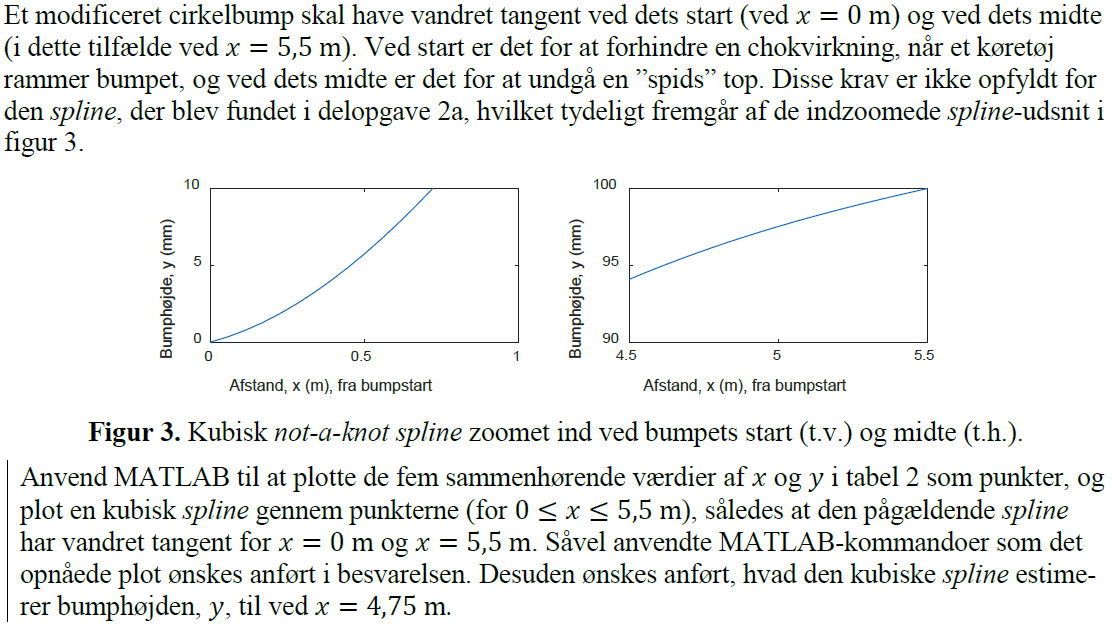

yy_cube = spline(x, [0 y 0], xx); % her til føjes en start hældning på kurven ved at 
% give et ekstra start til og slut tal til vektorene.
yy_cube_test = spline(x, [0 y 0], x_test)

yy_cube_test = 97.1982

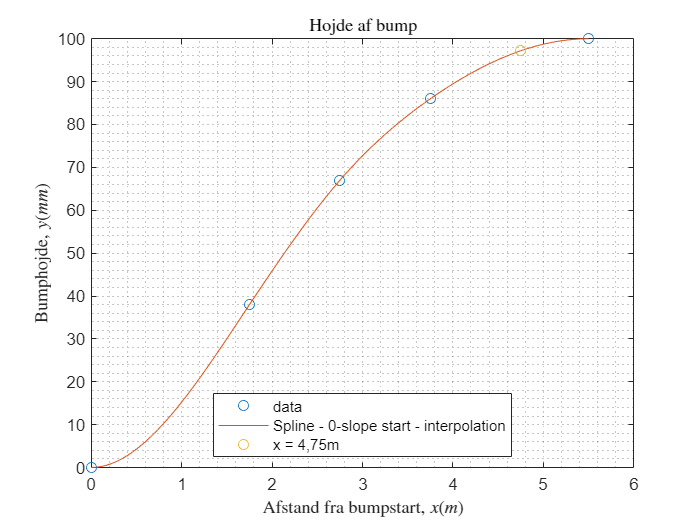


plot(x,y, 'o', 'DisplayName', 'data') %data plottes
hold on
plot(xx, yy_cube, 'DisplayName', 'Spline - 0-slope start - interpolation') %data plottes
plot(x_test,yy_cube_test, 'o', 'DisplayName', 'x = 4,75m') %data plottes

% formalier
legend('location', 'best')
title('Hojde af bump', 'interpreter', 'latex')
xlabel('Afstand fra bumpstart, $x(m)$', 'interpreter', 'latex')
ylabel('Bumphojde, $y(mm)$', 'interpreter', 'latex')
grid('minor')
hold off

**Vi fårspledes at bumpest højde er 97mm ved 4,75m.**

### (2c)

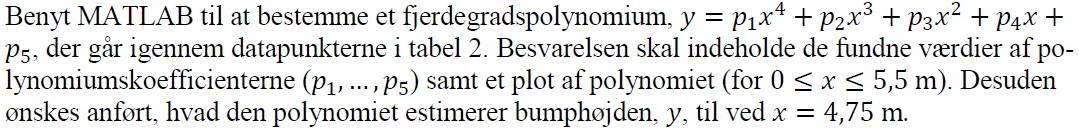

P_fit = polyfit(x, y, 4);
P_val = polyval(P_fit, xx);
P_val_test = polyval(P_fit, x_test)

P_val_test = 94.7129

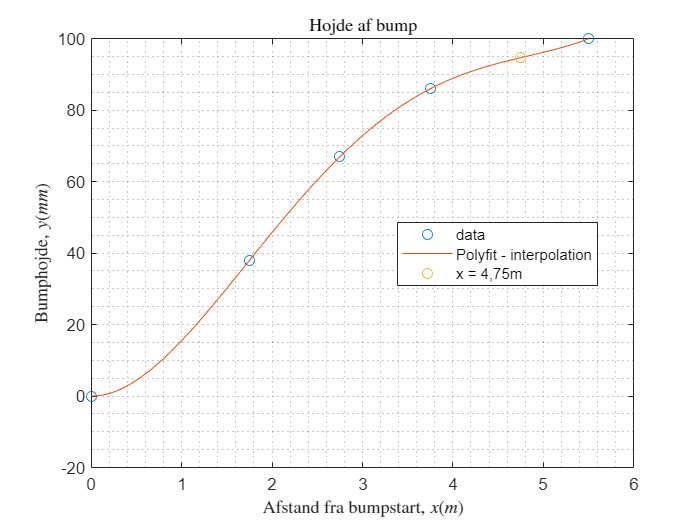

plot(x,y, 'o', 'DisplayName', 'data') %data plottes
hold on
plot(xx, P_val, 'DisplayName', 'Polyfit - interpolation') %data plottes
plot(x_test, P_val_test, 'o', 'DisplayName', 'x = 4,75m') %data plottes

% formalier
legend('location', 'best')
title('Hojde af bump', 'interpreter', 'latex')
xlabel('Afstand fra bumpstart, $x(m)$', 'interpreter', 'latex')
ylabel('Bumphojde, $y(mm)$', 'interpreter', 'latex')
grid('minor')
hold off

T = table(P_fit', ...
    VariableNames={'Polynomie coeficienter'}, ...
    RowNames={'p1', 'p2', 'p3', 'p4', 'p5'});
%, x', y', VariableNames={'Polynomie co', 'afstand x (m)', 'højde y (mm)'});
disp(T)

          Polynomie coeficienter
          ______________________

    p1             0.41936      
    p2             -5.4996      
    p3              20.923      
    p4            -0.30693      
    p5         -2.4145e-14      



**polynomiet coeficenter fremgår af tabellen hvor p5 kan siges at være 0**

**Vi fårspledes at bumpest højde er 95mm ved 4,75m.**

## Opgave 3

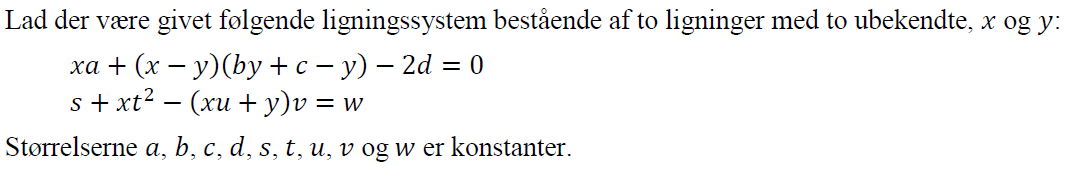

clear

### (3a)

Er ligningssystemet lineært eller ulineært? Begrund svaret.

syms x y a b c d s t u v w

f1 = x*a + (x - y) * (b * y + c - y) - 2*d; % = 0
f2 = s + x * t^2 - (x*u + y) * v - w; %=0
f = [expand(f1); expand(f2)]

$$f = \left(\begin{array}{c} a\,x-2\,d+c\,x-c\,y-x\,y-b\,y^{2}+y^{2}+b\,x\,y\\ x\,t^{2}+s-w-v\,y-u\,v\,x \end{array}\right)$$

Vi kan dog nu lave partieldifferentiering af de to ligninger for at sikre os.

for i = 1:length(f)
    fprintf(" Ligning %d patielt differentiert for alle varable", i)
    diff(f(i), x)
    diff(f(i), y)
end

 Ligning 1 patielt differentiert for alle varable

$$ans = a+c-y+b\,y$$

$$ans = 2\,y-x-c+b\,x-2\,b\,y$$

 Ligning 2 patielt differentiert for alle varable

$$ans = t^{2}-u\,v$$

$$ans = -v$$

Eller vi kan bruge den indbyggede jacobian function

jacobian(f, [x, y])

$$ans = \left(\begin{array}{cc} a+c-y+b\,y & 2\,y-x-c+b\,x-2\,b\,y\\ t^{2}-u\,v & -v \end{array}\right)$$

Det ses at alle afledning IKKE giver konstanter og dermed må ligningerne være ulineær.

### (3b)

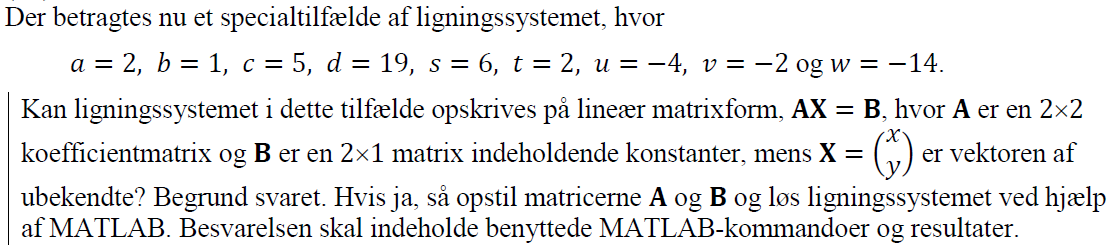

clear
syms x y
a = 2;
b = 1;
c = 5;
d = 19;
s = 6;
t = 2;
u = -4;
v = -2;
w = -14;
f1 = x * a + (x - y) * (b * y + c - y) - 2*d == 0;
f2 = s + x * t^2 - (x*u + y) * v == w;
f = [f1; f2]

$$f = \left(\begin{array}{c} 7\,x-5\,y-38=0\\ 2\,y-4\,x+6=-14 \end{array}\right)$$

Ja det kan det da vi har 2 ligninger med to ubekendte. Dette kan gøres i hånden ved at opstille matrixen med x og y coeficenter lig med en vektor med resultaterne. eller vi kan bruge matlab.

[A, B] = equationsToMatrix(f)

$$A = \left(\begin{array}{cc} 7 & -5\\ -4 & 2 \end{array}\right)$$

$$B = \left(\begin{array}{c} 38\\ -20 \end{array}\right)$$

X = [x; y]

$$X = \left(\begin{array}{c} x\\ y \end{array}\right)$$

Vi har således Matrixen A og resultat vektoren B  samt varable vektoren X

X = A\B

$$X = \left(\begin{array}{c} 4\\ -2 \end{array}\right)$$

X = linsolve(A,B)

$$X = \left(\begin{array}{c} 4\\ -2 \end{array}\right)$$

**Vi får således x = 4 og y = -2.**

### (3c)

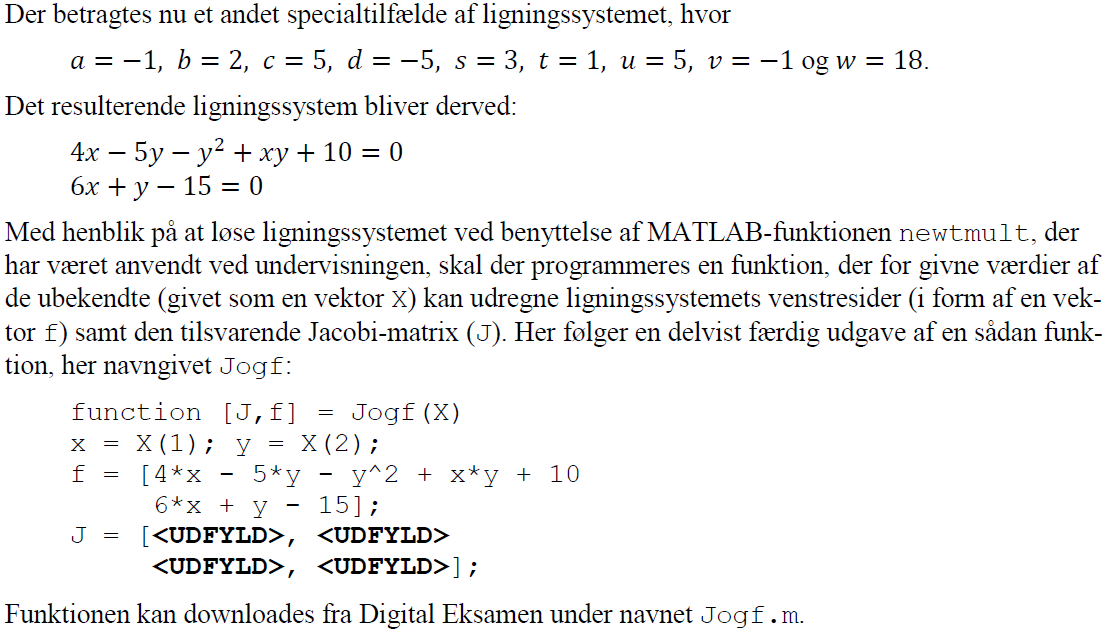

clear
syms x y
a = -1;
b = 2;
c = 5;
d = -5;
s = 3;
t = 1;
u = 5;
v = -1;
w = 18;

For at finde indputs til jacobi matrixen laver vi partiel differention.

f = [4*x - 5*y - y^2 + x*y + 10 
    6*x + y - 15];

for i = 1:length(f)
    fprintf(" Ligning %d patielt differentiert for alle varable", i)
    diff(f(i), x)
    diff(f(i), y)
end

 Ligning 1 patielt differentiert for alle varable

$$ans = y+4$$

$$ans = x-2\,y-5$$

 Ligning 2 patielt differentiert for alle varable

$$ans = 6$$

$$ans = 1$$

eller med den indbyggede function

jacobian(f)

$$ans = \left(\begin{array}{cc} y+4 & x-2\,y-5\\ 6 & 1 \end{array}\right)$$

### (3d)

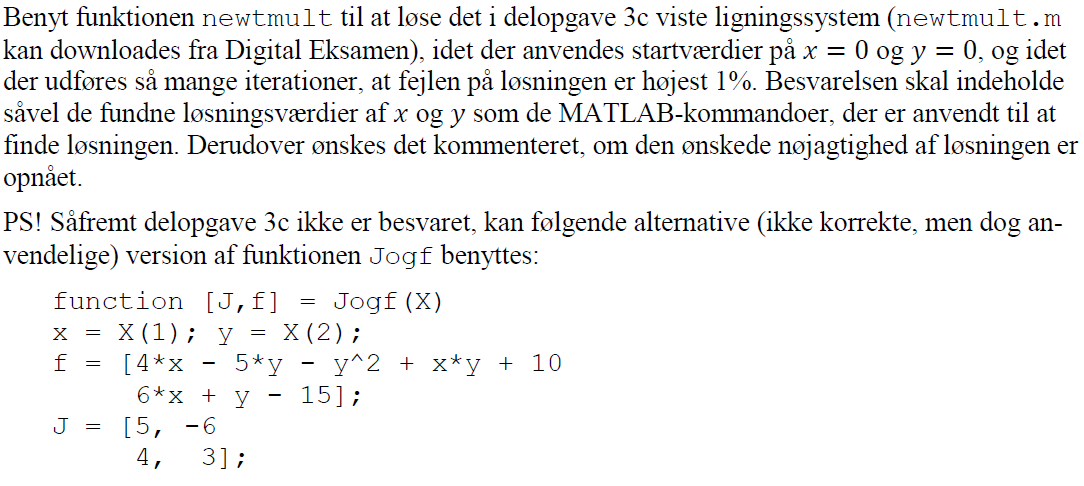

clear
x = 0;
y = 0;
x0 = [0; 0]; % i form af vector!!!
es = 1;

format long
[x_mult,f, ea,iter] = newtmult(@Jogf,x0,es)

x_mult =    1.999984372961770
   3.000093762229378


f =   -0.292522924483976
                   0


ea =    0.952790390625328


iter =      3


fejlen på x bliver 

x = x_mult(1);
x_err = abs(ea * x /100);
x_with_err = [x - x_err, x + x_err]

x_with_err =    1.980928714042182   2.019040031881358


**x er demed korrekt ned til og med 1 decimal 2,0.**

y = x_mult(2);
y_err = abs(ea * y /100);
y_with_err = [y - y_err, y + y_err]

y_with_err =    2.971509157153107   3.028678367305650


**y er korrekt ned til og med 1 decimal 3,0.**

### (3e)

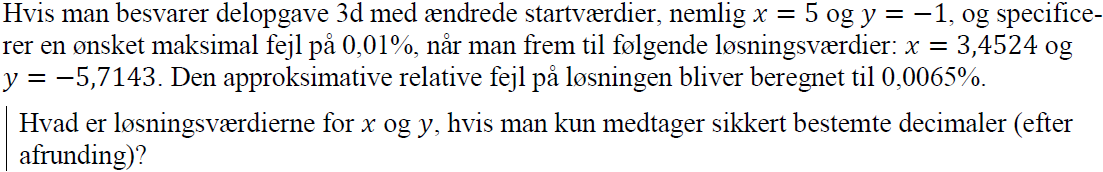

ea = 0.0065;
x = 3.4524;
x_err = abs(ea * x /100);
x_with_err = [x - x_err, x + x_err]

x_with_err =    3.452175594000000   3.452624406000000


**x er demed korrekt ned til og med 2 decimal 3,45.**

y = -5.7143;
y_err = abs(ea * y /100);
y_with_err = [y - y_err, y + y_err]

y_with_err =   -5.714671429500000  -5.713928570499999


**y er demed korrekt ned til og med 2 decimal -5,71.**

## Opgave 4

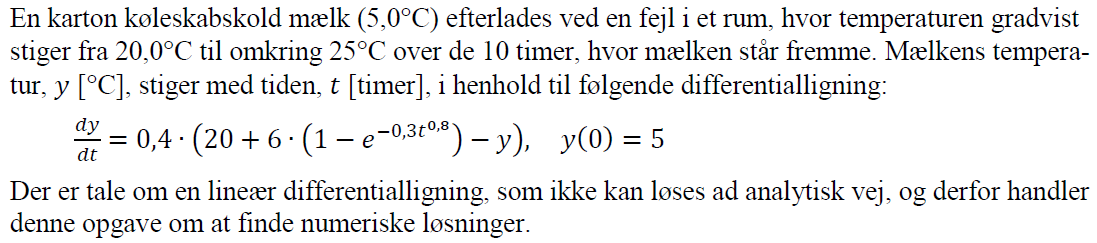

clear


### (4a)

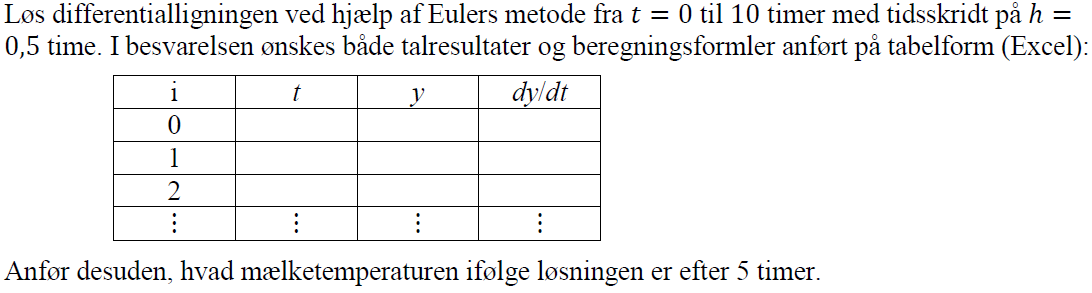

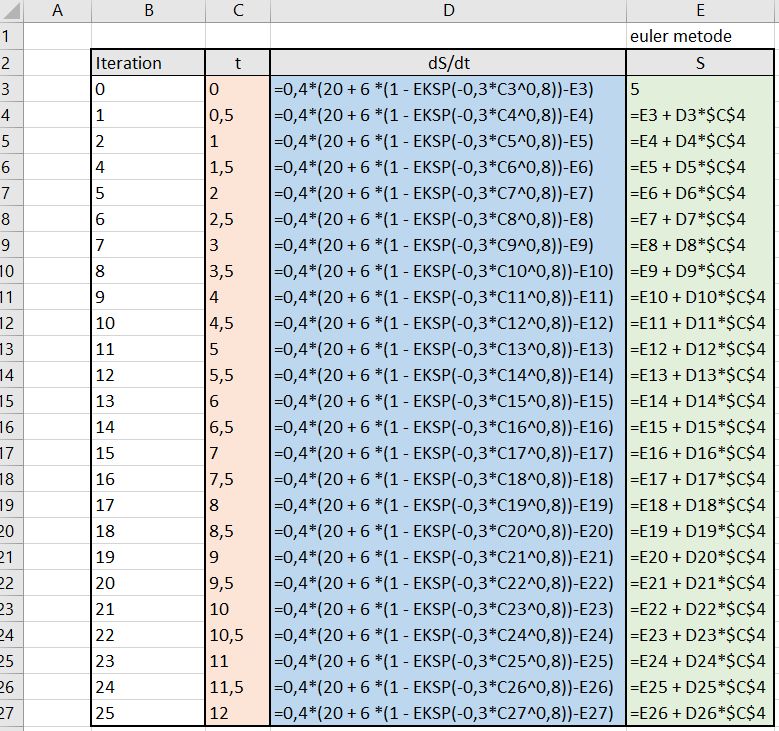

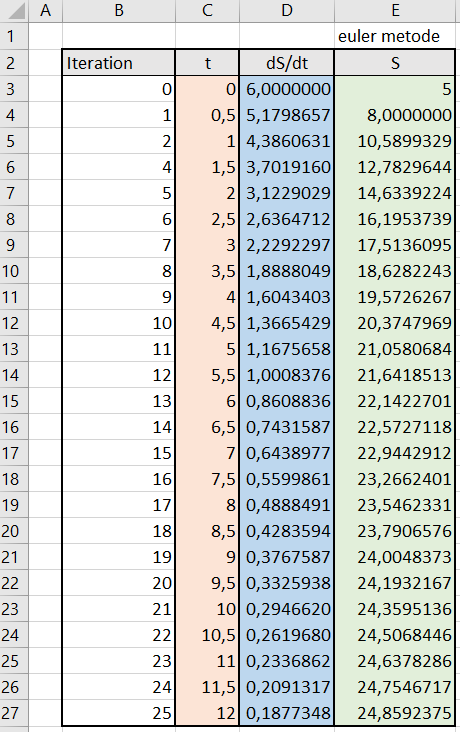

Efter 5 timer er mælkens temperatur 21,1 grader

### (4b)

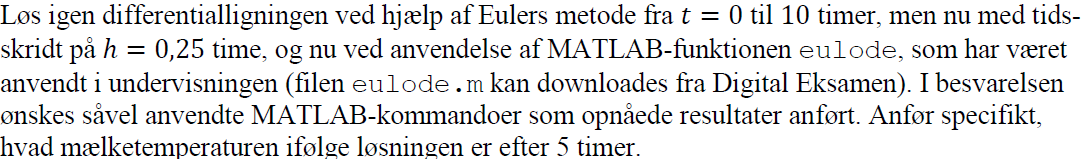

### (4c)

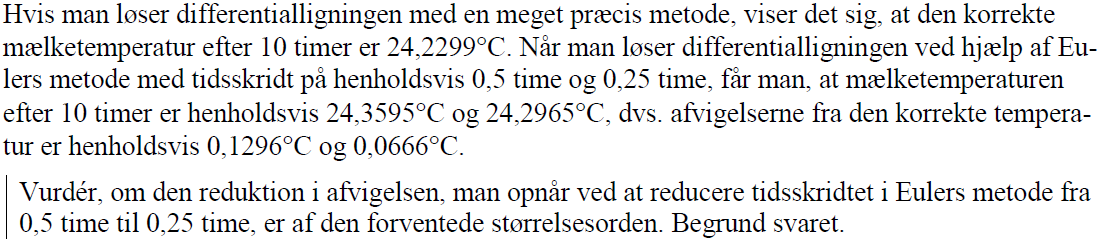

## Plot koder

% %der plottes
% fplot(f(x),[-4, 5], 'DisplayName', 'funktion') %data plottes
% hold on
% yline(0, '--', 'DisplayName', '0-linje')
% xline([-3], 'g--', 'DisplayName', 'Rødder'); 
% xline([0 4], 'g--','HandleVisibility','off');
% 
% % formalier
% legend('location', 'best')
% title('Kontinuert funktion', 'interpreter', 'latex')
% xlabel('$x$', 'interpreter', 'latex')
% ylabel('$f(x)$', 'interpreter', 'latex')
% grid('minor')
% hold off